close all;
clear all;
clc;

## Set-up sperimentale

Il progetto si concentra nell'elaborazione ed analisi del vogatore,esercizio ginnico svolto grazie ad un'attrezzo apposito per riprodurre il gesto del canottiere. In particolare, il progetto si concentrerà sull'analisi del moto delle gambe.

Il sistema ottico Polaris Vicra ci permette di raccogliere le informazioni sulla cinematica del movimento durante la vogata. Esso utilizza gruppi di marker retroriflettenti passivi che permettono, grazie ad una geometria pre-definita, un riconoscimento automatico di quest'ultimi nell'immagine acquisita dalle telecamere. Le telecamere vengono poste in modo da inquadrare l'ambiente dove avverà il movimento e i markers, mentre i tools vengono posti in posizioni stragetici utili per la ricostruzione del movimento sull'esecutore.

In questo progetto i tre tools vengono posizionati all'estremità delle sezioni della gamba dell'esecutore: caviglia, ginocchio e anca. Per rendere più veritiera la misurazione del moto, i tools devono aderire il più possibile al corpo dell'esercutore.

## Schema cinematico

Le gambe dell'esecutore possono essere modellizzate attraverso due aste collegate tra loro da una cerniera. La seconda estremità dell'asta, che indica la tibia, viene modellizzata con una cerniera incastrata a terra, mentre quella del femore con un carrello. Il sistema così raffigurato presenta un grado di libertà. Il sistema viene studiato come un manivellismo deviato.

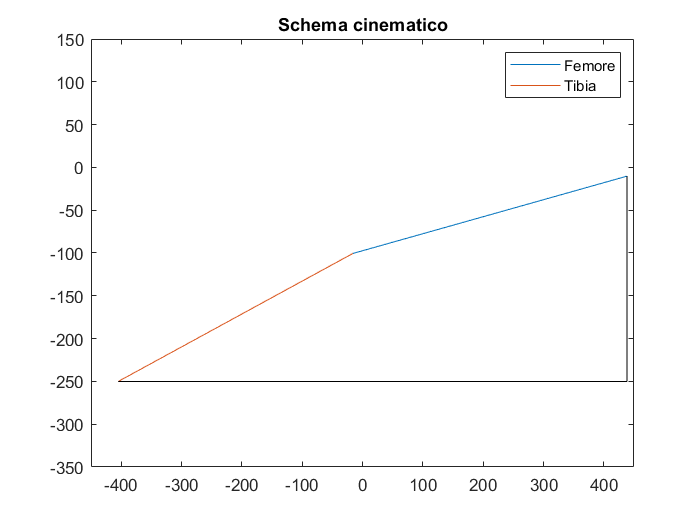

load ('data_stud.mat','zero');
M=zero;
Xa=M(:,1)*10^(-3); %metri
Ya=M(:,2)*10^(-3);
Xg=M(:,3)*10^(-3);
Yg=M(:,4)*10^(-3);
Xc=M(:,5)*10^(-3);
Yc=M(:,6)*10^(-3);

figure(1)
for i=1:96
    plot ([zero(i,1), zero(i,3)] , [zero(i,2), zero(i,4)])
    hold on
    plot ([zero(i,3), zero(i,5)] , [zero(i,4), zero(i,6)])
    hold on
    plot ([zero(i,1), zero(i,1)] , [zero(i,2), zero(i,6)],'Color','k')
    hold on
    plot ([zero(i,1), zero(i,5)] , [zero(i,6), zero(i,6)],'Color','k')
    xlim([-450 450])
    ylim ([-350 150])
    pause(0.05)
    hold off
end
legend ('Femore','Tibia')
title('Schema cinematico')

Creazione di un video per evidenziare il movimento dell'arto.

%figure
%writeObj=VideoWriter('Gamba');
%writeObj.FrameRate=10;
%open(writeObj);
%for i=1:96
%    plot ([zero(i,1), zero(i,3)] , [zero(i,2), zero(i,4)],'Color','k')
%    hold on
%    plot ([zero(i,3), zero(i,5)] , [zero(i,4), zero(i,6)],'Color','k')
%    xlim([-450 450])
%    ylim ([-350 150])
%    pause(0.05)
%    hold off
%    frame=getframe(gcf);
%    writeVideo(writeObj,frame)
%    pause(0.1)
%end
%close(writeObj);

## Analisi cinematica

STEP3.1 Lunghezza delle sezioni prossimali e distali della gamba

La matrice data indica le coordinate dei markers, da cui si può ricavare le componenti distanza delle sezioni e infine, applicando pitagora si ottiene la lunghezza delle sezioni. La differenza di lunghezza tra la stessa sezione è dovuta in parte al posizionamento dei markers, alla vibrazione del sedile e alle approsimazioni dei calcoli; prendo quindi in considerazione la media della lunghezza delle sezioni.

G1x=Xg-Xa;
G1y=Yg-Ya;
G2x=Xc-Xg;
G2y=Yc-Yg;
Femore=sqrt(G1x.^2+G1y.^2);
Tibia=sqrt(G2x.^2+G2y.^2);
Fm=mean(Femore);
Tm=mean(Tibia);

STEP3.2 Escursione angolare del ginocchio

Otteniamo il range of motion attraverso il prodotto scalare: conosciamo i vettori delle due sezioni, da cui otteniamo il prodotto scalare; conoscendo anche la norma delle sezioni, otteniamo l'angolo. Il range of motion è la differenza tra il massimo è il minimo del valore ottenuto.

for i=1:96
    b=[Xa(i)-Xg(i) Ya(i)-Yg(i)];
    c=[Xc(i)-Xg(i) Yc(i)-Yg(i)];
    ps=dot(b,c);
    norma=(norm(b)*norm(c));
    aa(i,1)=acosd(ps/(norm(b)*norm(c)));
end

Ma=max(aa);
ma=min(aa);
range=Ma-ma; %gradi

STEP3.3 Velocità e accelerazione orizzontale dell'anca

Il tempo viene fornito dal sistema Polaris: esso si ricava dalla frequenza di campionamento (20 Hz).

Ottengo la velocità dai dati della matrice fornita e l'accelerazione come derivata della velocità.

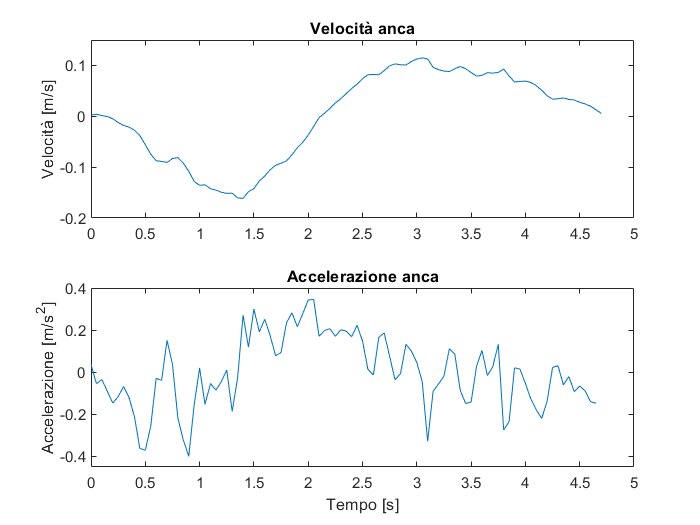

deltat=1/20; %secondi
for j=1:95
    v(j,1)=(Xa(j+1)-Xa(j))/deltat; %m/s
end

for k=1:94
    a(k,1)=(v(k+1)-v(k))/deltat; %m/s^2
end

figure(2)
subplot(2,1,1)
t=0:deltat:94*deltat;
plot(t,v(:,1))
title('Velocità anca')
ylabel('Velocità [m/s]');
ylim([-0.2 0.15])
subplot(2,1,2)
tt=0:deltat:93*deltat;
plot(tt,a(:,1))
title('Accelerazione anca')
xlabel('Tempo [s]');
ylabel('Accelerazione [m/s^2]');
ylim([-0.45 0.4])

STEP3.4 Velocità e accelerazione angolare

La velocità e l'accelerazione angolare vengono risolti attraverso la chiusura cinematica. Definisco quindi alpha e beta, gli angoli dei segmenti con l'orizzontale.

Ho inserito un confronto grafico con la velocità e l'accelerazione angolare sperimentale.

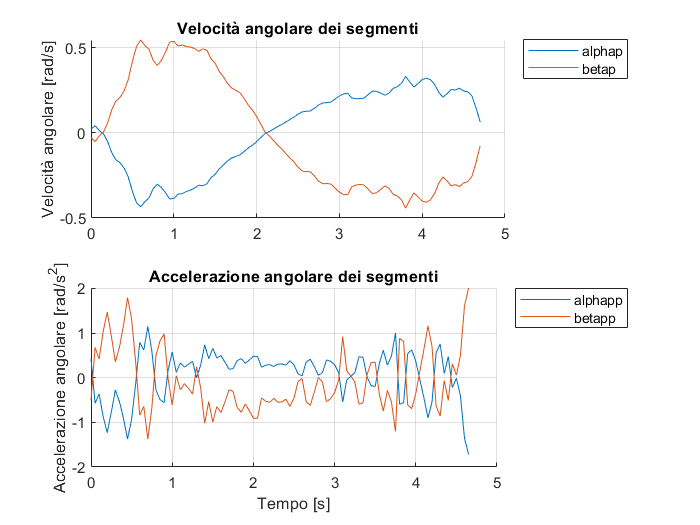

for i=1:96
    alpha(i,1)=pi+atan(G1y(i)/G1x(i)); %rad per impostazioni matlab
    beta(i,1)=pi+atan(G2y(i)/G2x(i));
end

for j=1:95
    A2=[-Fm*sin(alpha(j+1)) -Tm*sin(beta(j+1));
        Fm*cos(alpha(j+1)) Tm*cos(beta(j+1))];
    TN2=[-v(j); 0];
    VV=A2\TN2;
    alphap(j,1)=VV(1); %rad/s velocità angolare del femore
    betap(j,1)=VV(2); %rad/s velocità angolare della tibia
end

for k=1:94
    A2=[-Fm*sin(alpha(k+2)) -Tm*sin(beta(k+2));
         Fm*cos(alpha(k+2)) Tm*cos(beta(k+2))];
    TN3=[-a(k)+Fm*alphap(k+1)^2*cos(alpha(k+2))+Tm*betap(k+1)^2*cos(beta(k+2));
        Fm*alphap(k+1)^2*sin(alpha(k+2))+Tm*betap(k+1)^2*sin(beta(k+2))];
    AA=A2\TN3;
    alphapp(k,1)=AA(1); %rad/s^2 accelerazione angolare del femore
    betapp(k,1)=AA(2); %rad/s^2 accelerazione angolare della tibia
end

figure(3)
subplot(2,1,1)
hold on, grid on
t=0:deltat:94*deltat;
plot(t,alphap(:,1))
hold on
plot(t,betap(:,1))
ylabel('Velocità angolare [rad/s]');
legend('alphap','betap','Location','northeastoutside')
title('Velocità angolare dei segmenti')
subplot(2,1,2)
hold on, grid on
tt=0:deltat:93*deltat;
plot(tt,alphapp(:,1))
hold on
plot(tt,betapp(:,1))
xlabel('Tempo [s]');
ylabel('Accelerazione angolare [rad/s^2]');
legend('alphapp','betapp','Location','northeastoutside')
title('Accelerazione angolare dei segmenti')

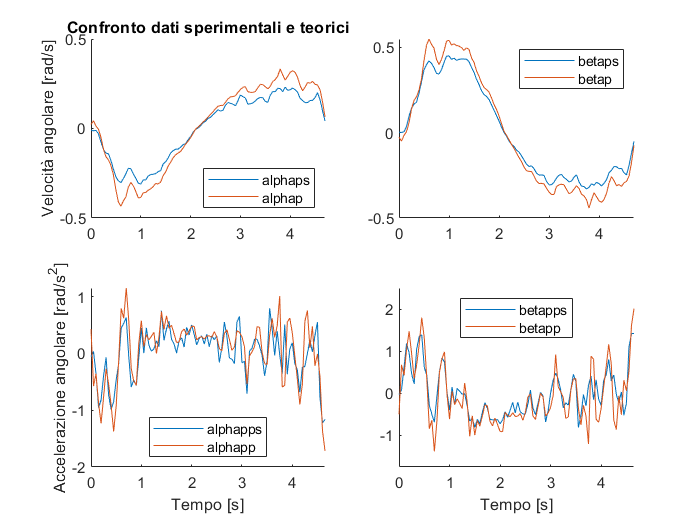

%dati sperimentali
for j=1:95
    alphaps(j,1)=(alpha(j+1)-alpha(j))/deltat;
    betaps(j,1)=(beta(j+1)-beta(j))/deltat;
end

for k=1:94
    alphapps(k,1)=(alphaps(k+1)-alphaps(k))/deltat;
    betapps(k,1)=(betaps(k+1)-betaps(k))/deltat;
end

figure(4)
subplot(2,2,1)
hold on
t=0:deltat:94*deltat;
plot(t,alphaps(:,1))
hold on
plot(t,alphap(:,1))
ylabel('Velocità angolare [rad/s]');
legend('alphaps','alphap','Location','southeast')
title('Confronto dati sperimentali e teorici')
subplot(2,2,2)
hold on
t=0:deltat:94*deltat;
plot(t,betaps(:,1))
hold on
plot(t,betap(:,1))
legend('betaps','betap')
subplot(2,2,3)
hold on
t=0:deltat:93*deltat;
plot(t,alphapps(:,1))
hold on
plot(t,alphapp(:,1))
ylabel('Accelerazione angolare [rad/s^2]');
xlabel('Tempo [s]')
legend('alphapps','alphapp','Location','south')
subplot(2,2,4)
hold on
t=0:deltat:93*deltat;
plot(t,betapps(:,1))
hold on
plot(t,betapp(:,1))
xlabel('Tempo [s]')
ylim([-1.75 2.5])
legend('betapps','betapp','Location','north')

STEP3.5 Confronto tra velocità e accelerazione del ginocchio

Risoluzione teorica: attraverso il teorema di Rivals considerando come punto di riferiemento la caviglia.

vG=vC+cross(Betap,G2), aG=aG+cross(Betap,G2)-(Betap'*Betap)*G2

Risoluzione sperimentale: ottengo la velocità dai dati della matrice fornita e l'accelerazione come derivata della velocità.

Calcolo in entrambi i casi le componenti della velocità e dell'accelerazione.

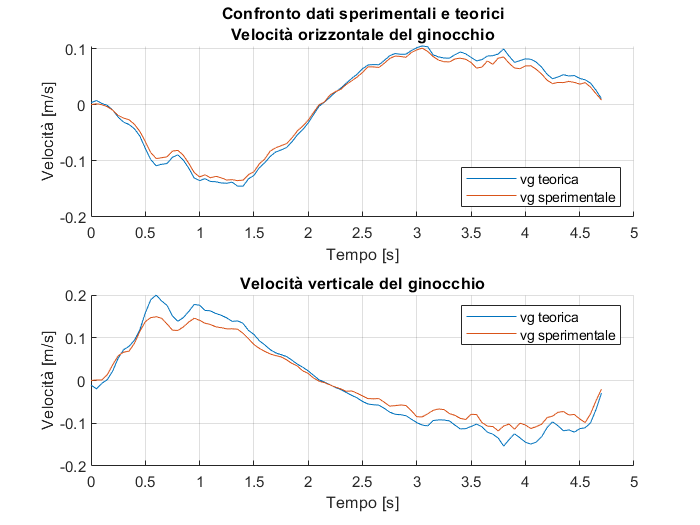

%teoria
for j=1:95
    G2=[-Tibia(j+1)*cos(beta(j+1)); -Tibia(j+1)*sin(beta(j+1));0];
    Betap=[0;0;betap(j)];
    vg(j,:)=cross(Betap,G2);
end

for k=1:94
    G2=[-Tibia(k+2)*cos(beta(k+2)); -Tibia(k+2)*sin(beta(k+2));0];
    Betap=[0;0;betap(k)];
    Betapp=[0;0;betapp(k)];
    ag(k,:)=cross(Betapp,G2)-(Betap'*Betap)*G2;
end

%dati sperimentali
for j=1:95
    vgx(j,1)=(Xg(j+1)-Xg(j))/deltat;
    vgy(j,1)=(Yg(j+1)-Yg(j))/deltat;
end

for k=1:94
    agx(k,1)=(vgx(k+1)-vgx(k))/deltat;
    agy(k,1)=(vgy(k+1)-vgy(k))/deltat;
end

figure(5)
subplot(2,1,1)
hold on, grid on
t=0:deltat:94*deltat;
plot(t,vg(:,1))
hold on
plot(t,vgx(:,1))
title({'Confronto dati sperimentali e teorici';'Velocità orizzontale del ginocchio'});
ylabel('Velocità [m/s]');
xlabel('Tempo [s]');
legend('vg teorica','vg sperimentale','Location','southeast');
subplot(2,1,2)
hold on, grid on
plot(t,vg(:,2))
hold on
plot(t,vgy(:,1))
title('Velocità verticale del ginocchio');
xlabel('Tempo [s]');
ylabel('Velocità [m/s]');
legend('vg teorica','vg sperimentale');

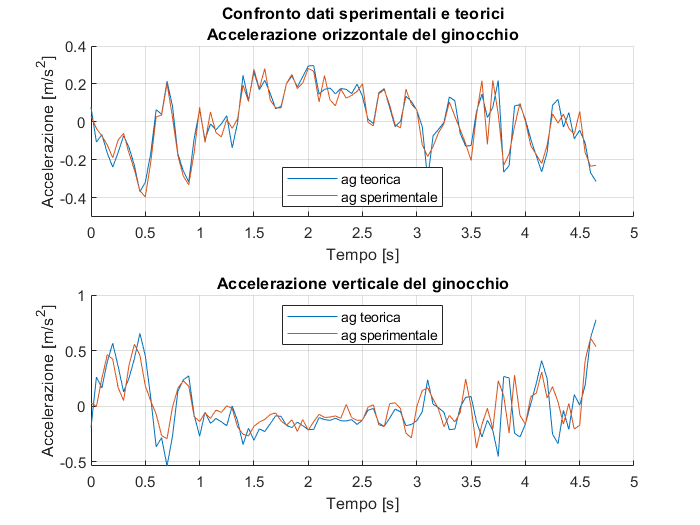

figure(6)
subplot(2,1,1)
hold on, grid on
tt=0:deltat:93*deltat;
plot(tt,ag(:,1))
hold on
plot(tt,agx(:,1))
title({'Confronto dati sperimentali e teorici';'Accelerazione orizzontale del ginocchio'});
ylabel('Accelerazione [m/s^2]');
xlabel('Tempo [s]');
ylim([-0.5 0.4])
legend('ag teorica','ag sperimentale','Location','south');
subplot(2,1,2)
hold on, grid on
plot(tt,ag(:,2))
hold on
plot(tt,agy(:,1))
title('Accelerazione verticale del ginocchio');
xlabel('Tempo [s]');
ylabel('Accelerazione [m/s^2]');
legend('ag teorica','ag sperimentale','Location','north');

Le differenze verticali sono dovute alle vibrazioni.

## Dinamica

STEP4.1 Posizione del baricentro delle sezioni della gamba

I dati forniti ci indicano altezza e peso dell'individuo. Attraverso le tabelle antropometriche risalgo alla distanza dei baricentri delle sezioni della gamba.

Studio l'atto di moto considerato (alphaprimo=170° e velocità positiva), individuo il valore che più si avvicina all'angolo dato e la sua posizione all'interno del vettore alpha. Calcolo poi tutti i dati in funzione di quest'ultimo.

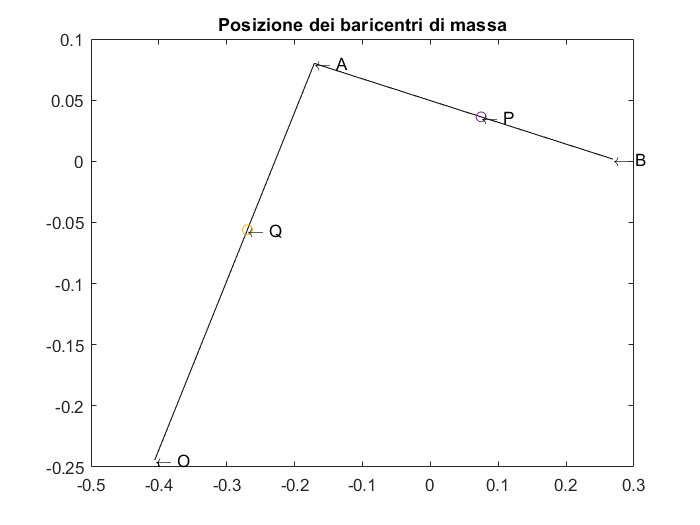

h=1.80; %m
alphaprimo=170; %gradi
alphaprimo=deg2rad(alphaprimo); %rad
Td=(0.285-0.039)*h;
Fd=(0.530-0.285)*h;
PB=0.433*Fm;
QA=0.433*Tm;
PA=Fm-PB;
QO=Tm-QA;

% velocità sedile
alphamin=abs(alpha(:,1)-alphaprimo);
Alpham=find(alphamin==min(alphamin));
if v(Alpham)>0
    va=v(Alpham);
elseif v(Alpham)<0
    va=0;
end
va=[va,0,0];
aa=[a(49,1),0,0];
Alphad=alpha(49,1);
Betad=beta(49,1)-pi;
Alphapd=[0,0,alphap(49,1)];
Betapd=[0,0,betap(49,1)];
Alphappd=[0,0,alphapp(49,1)];
Betappd=[0,0,betapp(49,1)];
Vg=[vgx(49,1) vgy(49,1) 0];
Ag=[agx(49,1) agy(49,1) 0];
Q=[zero(Alpham,5)*0.001+QO*cos(Betad),zero(Alpham,6)*0.001+QO*sin(Betad) ,0];
P=[zero(Alpham,1)*0.001+PB*cos(Alphad),zero(Alpham,2)*0.001+PB*sin(Alphad),0];

figure(7)
plot([zero(Alpham,1)*0.001, zero(Alpham,3)*0.001] , [zero(Alpham,2)*0.001, zero(Alpham,4)*0.001],'Color','k')
hold on
plot([zero(Alpham,3)*0.001, zero(Alpham,5)*0.001] , [zero(Alpham,4)*0.001, zero(Alpham,6)*0.001],'Color','k')
hold on
scatter(Q(1,1),Q(1,2))
hold on
scatter(P(1,1),P(1,2))
text(zero(Alpham,1)*0.001,zero(Alpham,2)*0.001,'\leftarrow B')
text(zero(Alpham,3)*0.001,zero(Alpham,4)*0.001,'\leftarrow A')
text(zero(Alpham,5)*0.001,zero(Alpham,6)*0.001,'\leftarrow O')
text(P(1,1),P(1,2),'\leftarrow P')
text(Q(1,1),Q(1,2),'\leftarrow Q')
title('Posizione dei baricentri di massa')

STEP4.2/4.3 Vettore velocità e accelerazione dei centri di massa

Attraverso il teorema di Rivals considerando come punto di riferiemento la caviglia per il baricentro della tibia e l'anca per il baricentro del femore.

Definisco prima i vettori coordinate, utili per il prodotto vettoriale.

La tibia ruota (dot(Vq,OQ)=0), mentre il femore roto-trasla.

OP=[Td*cos(Betad)+PA*cos(Alphad), Td*sin(Betad)-PA*sin(Alphad),0];
OQ=[QO*cos(Betad), QO*sin(Betad),0];
OA=[Td*cos(Betad), Td*sin(Betad), 0];
OB=[Td*cos(Betad)+Fd*cos(Alphad), Td*sin(Betad)+Fd*sin(Alphad),0];
AP=[PA*cos(Alphad), PA*sin(Alphad), 0]; %da A
BP=[PB*cos(Alphad), PB*sin(Alphad), 0];
AB=AP+BP;

Vq=cross(Betapd,OQ);
Vp=va+cross(Alphapd,BP);
Aq=cross(Betappd,OQ)-(Betapd*Betapd')*OQ;
Ap=aa+cross(Alphappd,BP)-(Alphapd*Alphapd')*BP;

figure(8)
subplot(2,1,1)
plot ([zero(Alpham,1)*0.001, zero(Alpham,3)*0.001] , [zero(Alpham,2)*0.001, zero(Alpham,4)*0.001],'Color','k')
hold on
plot ([zero(Alpham,3)*0.001, zero(Alpham,5)*0.001] , [zero(Alpham,4)*0.001, zero(Alpham,6)*0.001],'Color','k')
hold on
quiver(P(1,1),P(1,2),Vp(1,1),Vp(1,2));
hold on
quiver(Q(1,1),Q(1,2),Vq(1,1),Vq(1,2));
text(zero(Alpham,1)*0.001,zero(Alpham,2)*0.001,'\leftarrow B')
text(zero(Alpham,3)*0.001,zero(Alpham,4)*0.001,'\leftarrow A')
text(zero(Alpham,5)*0.001,zero(Alpham,6)*0.001,'\leftarrow O')
text(P(1,1),P(1,2),'\leftarrow P')
text(Q(1,1),Q(1,2),'\leftarrow Q')
legend('','','Vp','Vq','Location','southeast')
title('Velocità dei baricentri dei segmenti')
subplot(2,1,2)
plot ([zero(Alpham,1)*0.001, zero(Alpham,3)*0.001] , [zero(Alpham,2)*0.001, zero(Alpham,4)*0.001],'Color','k')
hold on
plot ([zero(Alpham,3)*0.001, zero(Alpham,5)*0.001] , [zero(Alpham,4)*0.001, zero(Alpham,6)*0.001],'Color','k')
hold on
quiver(P(1,1),P(1,2),Ap(1,1),Ap(1,2));
hold on
quiver(Q(1,1),Q(1,2),Aq(1,1),Aq(1,2));
text(zero(Alpham,1)*0.001,zero(Alpham,2)*0.001,'\leftarrow B')
text(zero(Alpham,3)*0.001,zero(Alpham,4)*0.001,'\leftarrow A')
text(zero(Alpham,5)*0.001,zero(Alpham,6)*0.001,'\leftarrow O')
text(P(1,1),P(1,2),'\leftarrow P')
text(Q(1,1),Q(1,2),'\leftarrow Q')
legend('','','Ap','Aq','Location','southeast')
title('Accelerazione dei baricentri dei segmenti')

STEP4.4 Calcolo coppia muscolare

E' possibile trovare la coppia muscolare attraverso il teorema dell'energia cinetica, considerando le quattro forze peso, le forze e i momenti d'inerzia.

Inserisco anche il controllo attraverso la risoluzione dl sistema per avere un confronto tra i dati ricavati.

m=94; %Kg
Leg=2*0.0465*m;
Thigh=2*0.1*m;
Foot=2*0.0145*m;
Body=m-(Thigh+Leg+Foot);
Ct=0.323*Fm;
Cl=0.302*Tm;
Vs=[v(49),0,0];
As=[a(49),0,0];

Jt=Thigh*Ct^2;
Jl=Leg*Cl^2;
Fpf=[0,-Foot*9.81,0]; %N
Fpl=[0,-Leg*9.81,0];
Fpt=[0,-Thigh*9.81,0];
Fpb=[0,-Body*9.81,0];

syms C
C=[0,0,C]; %positiva antioraria
W=dot(Fpl,Vq)+dot(Fpt,Vp)+dot(Fpb,Vs)+dot(Fpf,[0,0,0])+dot(C,Alphapd);
dEdt=dot(Leg.*Aq,Vq)+dot(Jl.*Betappd,Betapd)+dot(Thigh.*Ap,Vp)+dot(Jt.*Alphappd,Alphapd)+dot(Body.*As,Vs);
C=solve(W==dEdt);
Cm=round(C,3); %Kg*m^2/s^2 oraria

%controllo attraverso la risoluzione del sistema
Aff=[1 0 0 0 0 0;
    0 1 1 0 0 0;
    -AB(1,2) 0 -abs(AB(1,1)) 1 0 0;
    -1 0 0 0 1 0;
    0 0 -1 0 0 1;
    OA(1,2) 0 -OA(1,1) 0 0 0];
bff=[Thigh*Ap(1,1)+Body*As(1,1);
    (Thigh+Body)*9.81+Thigh*Ap(1,2);
    sum(-cross(BP,Fpt)-cross(BP,Thigh.*Ap)+Jt.*Alphappd);
    Leg*Aq(1,1);
    (Foot+Leg)*9.81+Leg*Aq(1,2);
    sum(-cross(OQ,Fpl)-cross(OQ,Leg.*Aq)+Jl.*Betappd)];
FF=Aff\bff;
Cm2=FF(4); %positiva antioraria

STEP4.5 Forza d'attrito dinamico

Attraverso lo studio della statica trovo le reazioni vincolari, la forza d'attrito e la coppia muscolare.

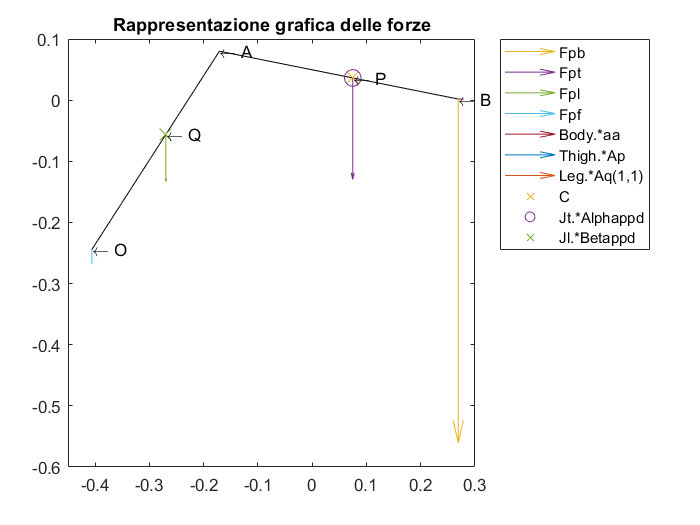

figure(9)
plot ([zero(Alpham,1)*0.001, zero(Alpham,3)*0.001] , [zero(Alpham,2)*0.001, zero(Alpham,4)*0.001],'Color','k')
hold on
plot ([zero(Alpham,3)*0.001, zero(Alpham,5)*0.001] , [zero(Alpham,4)*0.001, zero(Alpham,6)*0.001],'Color','k')
hold on
quiver(Xa(49,1),Ya(49,1),0,Fpb(1,2)*0.001);
hold on
quiver(P(1,1),P(1,2),0,Fpt(1,2)*0.001);
hold on
quiver(Q(1,1),Q(1,2),0,Fpl(1,2)*0.001);
hold on
quiver(Xc(49,1),Yc(49,1),0,Fpf(1,2)*0.001);
hold on
quiver(Xa(49,1),Ya(49,1),Body*aa(1,1)*0.001,0);
hold on
quiver(P(1,1),P(1,2),Thigh*Ap(1,1)*0.001,Thigh*Ap(1,2)*0.001);
hold on
quiver(Q(1,1),Q(1,2),Leg*Aq(1,1)*0.001,Leg*Aq(1,2)*0.001);
hold on
scatter(P(1,1),P(1,2),100,'x')
hold on
scatter(P(1,1),P(1,2),100)
hold on
scatter(Q(1,1),Q(1,2),100,'x');
xlim([-0.45 0.3])
text(zero(Alpham,1)*0.001,zero(Alpham,2)*0.001,'\leftarrow B')
text(zero(Alpham,3)*0.001,zero(Alpham,4)*0.001,'\leftarrow A')
text(zero(Alpham,5)*0.001,zero(Alpham,6)*0.001,'\leftarrow O')
text(P(1,1),P(1,2),'\leftarrow P')
text(Q(1,1),Q(1,2),'\leftarrow Q')
title('Rappresentazione grafica delle forze')
legend('','','Fpb','Fpt','Fpl','Fpf','Body.*aa','Thigh.*Ap','Leg.*Aq(1,1)','C','Jt.*Alphappd','Jl.*Betappd','Location','northeastoutside')

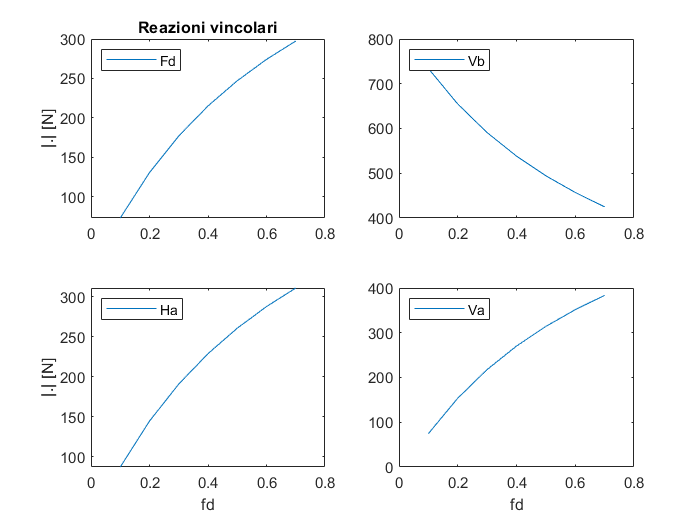

for fd=1:7
    Af=[1 -fd/10 0 0 0 0;
        0 1 1 0 0 0;
        -AB(1,2) 0 -abs(AB(1,1)) 1 0 0;
        -1 0 0 0 1 0;
        0 0 -1 0 0 1;
        OA(1,2) 0 -OA(1,1) 0 0 0];
    bf=[Thigh*Ap(1,1)+Body*As(1,1);
        (Thigh+Body)*9.81+Thigh*Ap(1,2);
        sum(-cross(BP,Fpt)-cross(BP,Thigh.*Ap)+Jt.*Alphappd);
        Leg*Aq(1,1);
        (Foot+Leg)*9.81+Leg*Aq(1,2);
        sum(-cross(OQ,Fpl)-cross(OQ,Leg.*Aq)+Jl.*Betappd)];
    F=Af\bf;
    Ha(fd,1)=F(1); %N verso destra positiva in femore
    Vb(fd,1)=F(2); %N verso l'alto positiva
    Va(fd,1)=F(3); %N verso l'alto positiva in femore
    Cd(fd,1)=F(4); %N antioraria positiva
    Ho(fd,1)=F(5); %N verso l'alto positiva
    Vo(fd,1)=F(6); %N verso l'alto positiva
    Fd(fd,1)=(fd/10)*abs(Vb(fd)); %N verso sinistra positiva
end

t=0.1:0.1:0.7;
figure(10)
subplot(2,2,1)
plot(t,Fd)
ylabel('|.| [N]')
legend('Fd','Location','northwest')
title('Reazioni vincolari')
subplot(2,2,2)
plot(t,Vb)
legend('Vb','Location','northwest')
subplot(2,2,3)
plot(t,Ha)
legend('Ha','Location','northwest')
xlabel('fd')
ylabel('|.| [N]')
subplot(2,2,4)
plot(t,Va)
legend('Va','Location','northwest')
xlabel('fd')

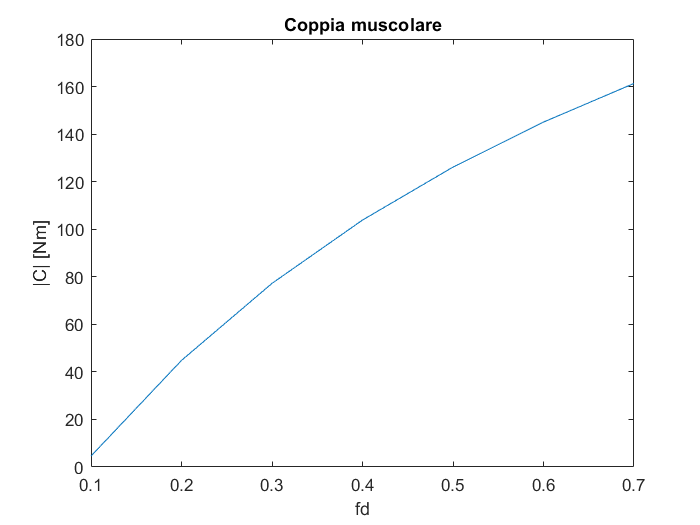

figure(11)
plot(t,Cd)
xlabel('fd')
ylabel('|C| [Nm]')
title('Coppia muscolare')

## Vibrazioni

STEP5.1 Calcolo della frequenza propria (f0) e dello smorzamento adimensionale (h) del sistema e risposta libera

La frequenza propria viene ricavata attraverso la pulsazione propria (sqrt(k/Body)), mentre lo smorzamento adimensionale attraverso il rapporto r/(2*Body*w0).

La risposta libera non smorzata si ottiene ponendo req=0 e risolvendo l'equazione differenziale calcolata; la soluzione aspettata sarà x(t)=A*cos(om*t+phi).

Calcolo, per completezza, anche la risposta libera smorzata, la cui soluzione attesa è x(t)=A*e^(-alpha*t)*sin(omd*t+phi) poichè lo smorzamento adimensionale è minore di 1.

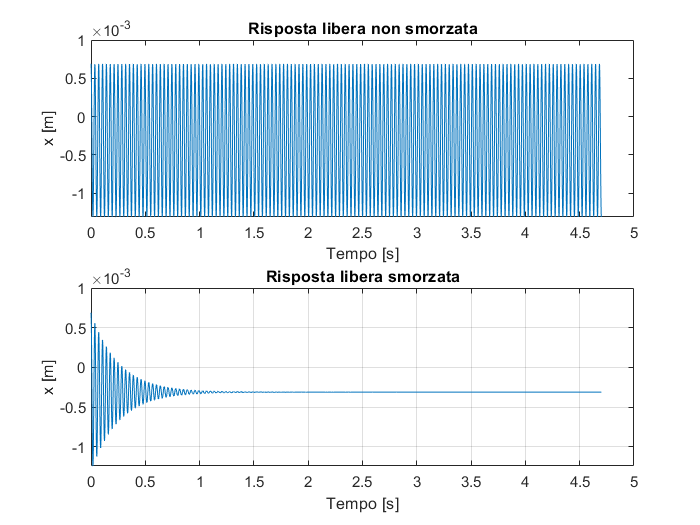

k=1e7/5;
r=500;
g=9.81;
Y0=1*0.001;
l=5*0.001;
xin=Y0;
xpin=0;
v_vec=[max(v)/2 (3*max(v))/4 max(v)];
OM_vec=(2*pi*v_vec)/l;
t=0:1/1000:94*1/20;

w0=sqrt(k/Body);
f0=w0/(2*pi); %Hz frequenza propria

delta=w0^2*(h^2-1); %distingue caso minore, uguale o maggiore di zero

xeq=-(Body*g)/k;
phi=atan(-xpin/xin/w0);
C=xin/cos(phi);
xt=C*cos(w0*t+phi);

h=r/(2*Body*w0); %smorzamento adimensionale
wd=w0*sqrt(1-h^2);
fd=wd/2/pi;
phid=atan(-xpin/xin/wd);
Cdd=xin/cos(phid);
xtd=(Cdd*cos(wd*t+phid)).*exp(-h*w0*t);

figure(12)
subplot(2,1,1)
plot(t,xt+xeq)
xlabel('Tempo [s]')
ylabel('x [m]')
title('Risposta libera non smorzata')
subplot(2,1,2)
plot(t,xtd+xeq),grid on, hold on
title('Risposta libera smorzata')
xlabel('Tempo [s]')
ylabel('x [m]')

STEP5.2 Risposta forzata del sistema

La risposta forzata si ottiene considerando le forzanti del sistema, risolvendo l'equazione differenziale; otteniamo così, tre risposte differenti, una per ogni valore della velocità considerato.

Considerando anche i grafici del modulo e della fase della funzione di trasferimento è possibile capire la posizione della velocità, facendo così una riflessione sulla zona (quasi-statica, di risonanza e sismografica) corrispondente.

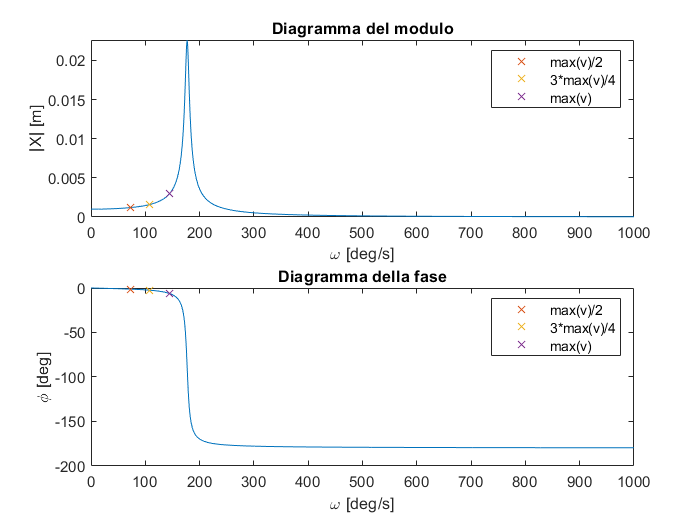

for i=1:3
    Feq_vec(i)=sqrt(k^2+(OM_vec(i)*r).^2)*xin;
    beta_vec(i)=atan(OM_vec(i)*r/k);
    x0_vec(i)=Feq_vec(i)./(-OM_vec(i).^2*Body+k+1i*OM_vec(i)*r);
    x0m_vec(i)=abs(x0_vec(i));
    phi_vec(i)=rad2deg(angle(x0_vec(i)));
end

OM=[0:0,1:1000];
Feq=sqrt(k^2+(OM*r).^2)*Y0;
beta=atan(OM*r/k);
x0=Feq./(-OM.^2*Body+k+1i*OM*r);
x0m=abs(x0);
phi=rad2deg(angle(x0));

figure(13)
subplot(2,1,1)
plot(OM,x0m)
hold on
plot(OM_vec(1,1),x0m_vec(1,1),'x')
hold on
plot(OM_vec(1,2),x0m_vec(1,2),'x')
hold on
plot(OM_vec(1,3),x0m_vec(1,3),'x')
ylabel('|X| [m]')
xlabel('\omega [deg/s]')
legend('','max(v)/2','3*max(v)/4','max(v)')
title('Diagramma del modulo')
subplot(2,1,2)
plot(OM,phi)
hold on
plot(OM_vec(1,1),phi_vec(1,1),'x')
hold on
plot(OM_vec(1,2),phi_vec(1,2),'x')
hold on
plot(OM_vec(1,3),phi_vec(1,3),'x')
ylabel('\phi [deg]')
xlabel('\omega [deg/s]')
legend('','max(v)/2','3*max(v)/4','max(v)')
title('Diagramma della fase')

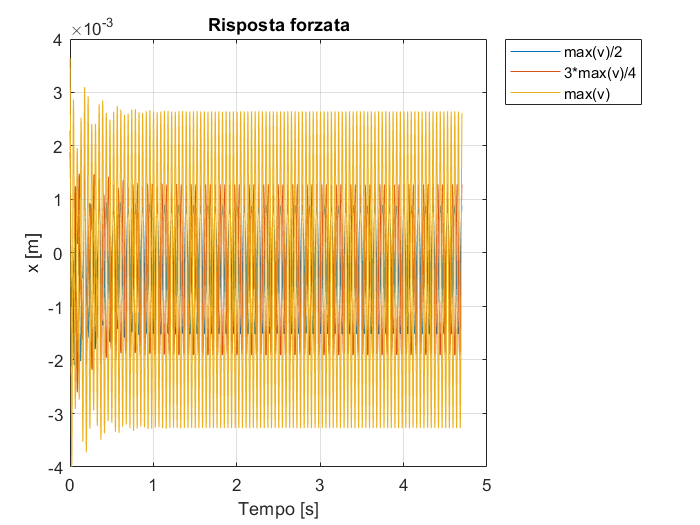

xtf1=x0m_vec(1,1)*cos(OM_vec(1,1)*t+beta_vec(1,1)+phi_vec(1,1)/180*pi);
xtf2=x0m_vec(1,2)*cos(OM_vec(1,2)*t+beta_vec(1,2)+phi_vec(1,2)/180*pi);
xtf3=x0m_vec(1,3)*cos(OM_vec(1,3)*t+beta_vec(1,3)+phi_vec(1,3)/180*pi);

figure(14)
plot(t,xtd+xeq+xtf1), grid on, hold on
plot(t,xtd+xeq+xtf2), grid on, hold on
plot(t,xtd+xeq+xtf3)
xlabel('Tempo [s]')
ylabel('x [m]')
title('Risposta forzata')
legend('max(v)/2','3*max(v)/4','max(v)','Location','northeastoutside')